This function has infinitely many continuous derivatives on the entire real line and looks very easy to approximate over $[-1,1]$.

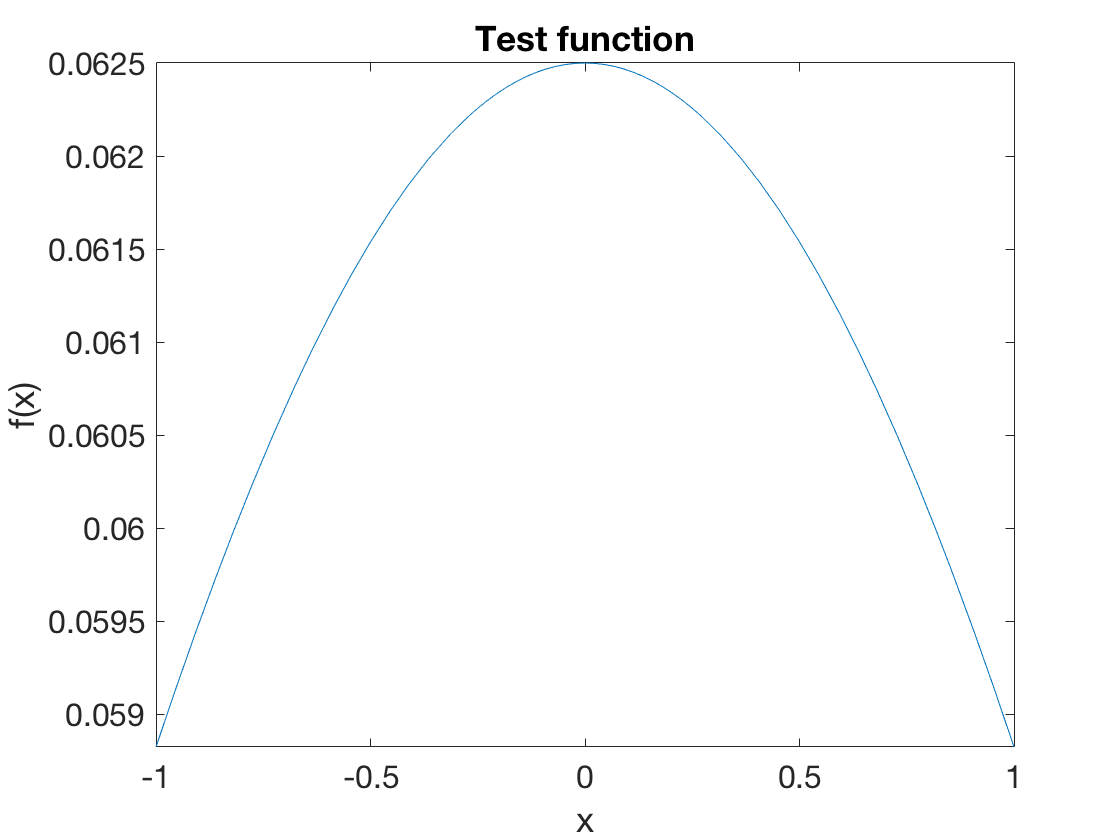

f = @(x) 1./(x.^2 + 16);
fplot(f,[-1 1])
xlabel('x'), ylabel('f(x)')    % ignore this line
title('Test function')    % ignore this line

We start by doing polynomial interpolation for some rather small values of $n$.

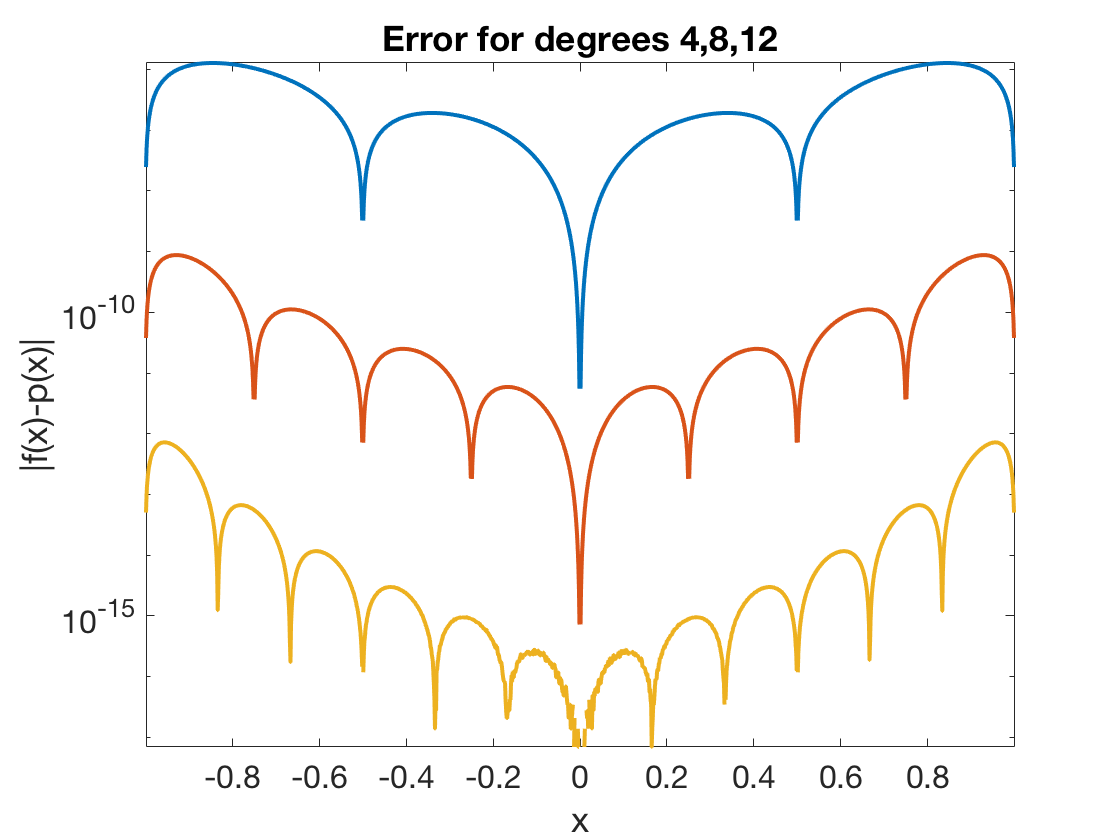

x = linspace(-1,1,1601)';
n = (4:4:12)';
for k = 1:length(n)
    t = linspace(-1,1,n(k)+1)';        % equally spaced nodes
    p = polyinterp(t,f(t));
    semilogy( x, abs(f(x)-p(x)) );
    hold on, axis tight    % ignore this line
end
axis tight, title('Error for degrees 4,8,12')   % ignore this line
xlabel('x'), ylabel('|f(x)-p(x)|')   % ignore this line

The convergence so far appears rather good, though not uniformly so. Now watch what happens as we continue to increase the degree.

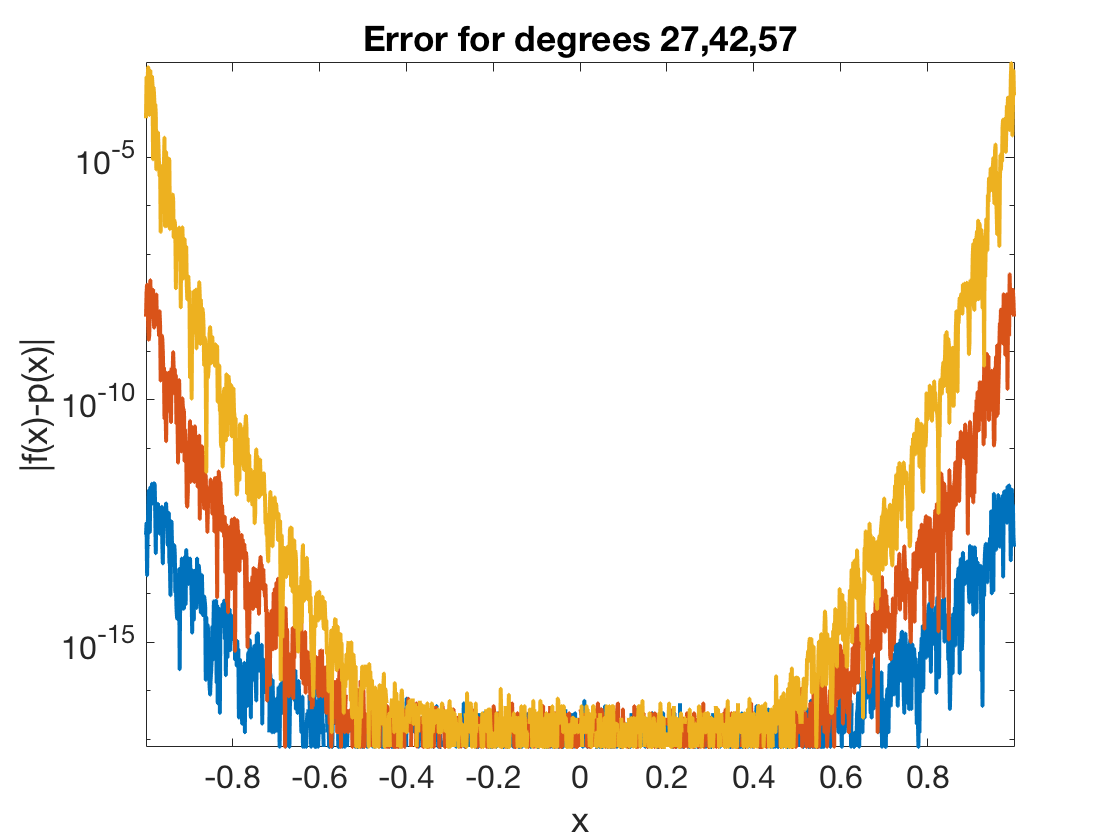

n = 12 + 15*(1:3)';  clf
for k = 1:length(n)
    t = linspace(-1,1,n(k)+1)';        % equally spaced nodes
    p = polyinterp(t,f(t));
    semilogy( x, abs(f(x)-p(x)) );
    hold on, axis tight    % ignore this line
end
axis tight, title('Error for degrees 27,42,57')   % ignore this line
xlabel('x'), ylabel('|f(x)-p(x)|')   % ignore this line

The convergence in the middle can't get any better than machine precision. So maintaining the growing gap between the center and the ends pushes the error curves upward exponentially fast at the ends, wrecking the convergence.